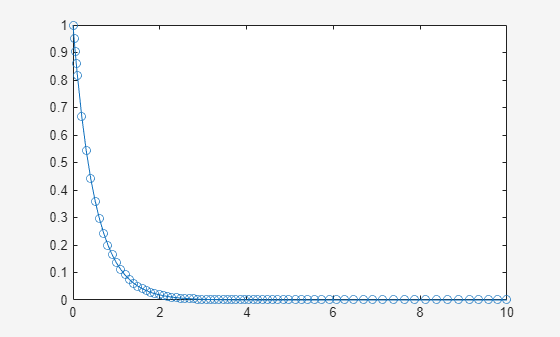

tic()
f=@(t,y)-2*y;
figure()
ode45(f,[0 10],[1])

toc()

Elapsed time is 0.523051 seconds.


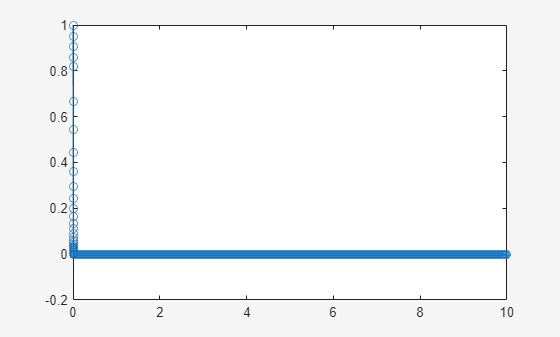

tic()
f=@(t,y)-20000*y;
ode45(f,[0 10],[1])

toc()

Elapsed time is 17.743291 seconds.


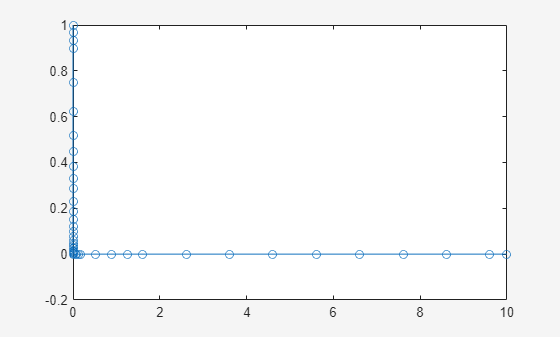

tic()
f=@(t,y)-20000*y;
ode15s(f,[0 10],[1])

figure()
toc()

Elapsed time is 0.223567 seconds.


## ----- Case 1: NonStiff MSD -----

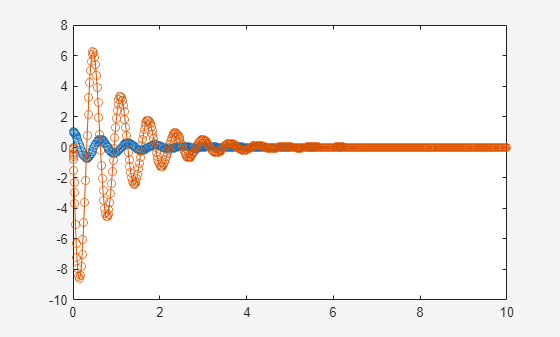

%% Mass–Spring–Damper (MSD) simulation with ode45
% Non-stiff vs stiff examples (same structure, different k)
% Save as: msd_ode45_both_cases.m

clear; clc; close all;
%% ----- Case 1: Non-stiff MSD (moderate k) -----
m1 = 1.0;         % kg
b1 = 2.0;         % N*s/m
k1 = 100.0;       % N/m  (non-stiff)

% Initial conditions: x(0)=1 m, xdot(0)=0 m/s
x0 = [1; 0];
% Time span (seconds) - non-stiff can use a longer window comfortably
tspan1 = [0 10];
% ODE function handle (state: y = [x; xdot])
f = @(t,y) [y(2);-k1/m1*y(1)-b1/m1*y(2)];
figure()
tic()
ode45(f, tspan1, x0);

toc()

Elapsed time is 0.628342 seconds.


## ----- Case 2: Stiff MSD (very large k) -----

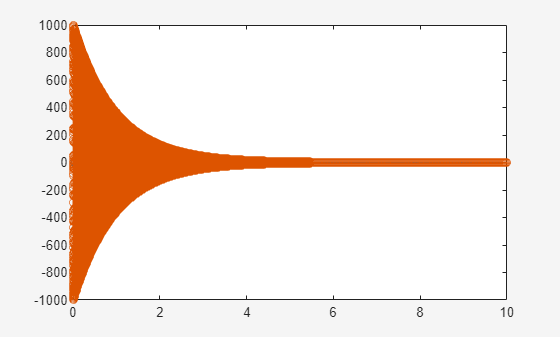

tic()
m2 = 1.0;         % kg
b2 = 2.0;         % N*s/m
k2 = 1e6;         % N/m  (stiff)
x0 = [1; 0];
% Time span (seconds) - stiff system has very fast dynamics,
% so keep this shorter or ode45 will take tiny steps.
tspan2 = [0 10];
f = @(t,y) [y(2);-k2/m2*y(1)-b2/m2*y(2)];
figure()
tic()
ode45(f, tspan2, x0);

toc()

Elapsed time is 4.779648 seconds.
